# Get Started with ROS

Robot Operating System (ROS) is a communication interface that enables different parts of a robot system to discover each other, and send and receive data between them. MATLAB® supports ROS with a library of functions that enables you to exchange data with ROS-enabled physical robots or robot simulators such as Gazebo®.

This example introduces how to:

- Set up ROS within MATLAB

- Get information about capabilities in a ROS network

- Get information about ROS messages

## ROS Terminology

- A *ROS network* comprises different parts of a robot system (such as a planner or a camera interface) that communicate over ROS. The network can be distributed over several machines.

- A *ROS master* coordinates the different parts of a ROS network. It is identified by a *Master URI* (Uniform Resource Identifier) that specifies the hostname or IP address of the machine where the master is running.

- A *ROS node *contains a collection of related ROS capabilities (such as publishers, subscribers, and services). A ROS network can have many ROS nodes.

- *Publishers*, *subscribers*, and *services* are different kinds of ROS entities that process data. They exchange data using *messages*.

- A publisher sends messages to a specific *topic* (such as "odometry"), and subscribers to that topic receive those messages. A single topic can be associated with multiple publishers and subscribers.

For more information, see [Robot Operating System (ROS)](docid:ros_gs.mw_79ccfff3-bdbd-46d8-899f-e5add5a50fad) and the [Concepts](https://wiki.ros.org/ROS/Concepts) section on the ROS website.

## Initialize ROS Network

Use [`rosinit`](docid:ros_ref.bupf5_j_1) to initialize ROS. By default, `rosinit` creates a *ROS master* in MATLAB and starts a *global node* that is connected to the master. The global node is automatically used by other ROS functions. 

rosinit

Use [`rosnode`](docid:ros_ref.bupf5_j_4)` list` to see all nodes in the ROS network. Note that the only available node is the global node created by `rosinit`.

rosnode list

Use `exampleHelperROSCreateSampleNetwork` to populate the ROS network with three additional nodes and sample publishers and subscribers.

exampleHelperROSCreateSampleNetwork

Use `rosnode list` again to see the three new nodes (`node_1`, `node_2`, and `node_3`).

rosnode list

The figure shows the current state of the ROS network. The MATLAB global node is disconnected since it currently does not have any publishers, subscribers or services.

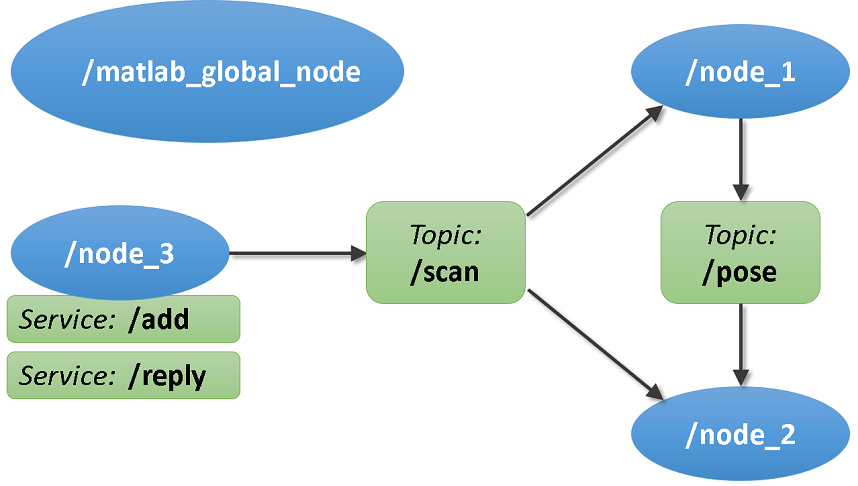

## Topics

Use [`rostopic`](docid:ros_ref.bupf5_j_14)` list` to see available topics in the ROS network. There are four active topics: `/pose`, `/rosout`, `/scan` and `/tf`. The default topics: `rosout` and `tf` are always present in the ROS network. The other two topics were created as part of the sample network.

rostopic list

Use `rostopic info ``<topicname>` to get specific information about a specific topic. The command below shows that `/node_1` publishes (sends messages to) the `/pose` topic, and `/node_2` subscribes (receives messages from) to that topic. See [Exchange Data with ROS Publishers and Subscribers](docid:ros_ug.mw_fa34dc6f-351e-4ab5-8680-46563496814b) for more information.

rostopic info /pose

Use [`rosnode`](docid:ros_ref.bupf5_j_4)` info ``<nodename>` to get information about a specific node. The command below shows that `node_1` publishes to `/pose`, `/rosout` and `/tf` topics, subscribes to the `/scan` topic and provides services: /node_1/get_loggers and /node_1/set_logger_level. The default logging services: get_loggers and set_logger_level are provided by all the nodes created in ROS network.

rosnode info /node_1

## Services

ROS services provide a mechanism for procedure calls across the ROS network. A *service client* sends a request message to a *service server*, which processes the information in the request and returns with a response message (see [Call and Provide ROS Services](docid:ros_ug.mw_70dbf089-5821-4e67-b96f-f659aea10c0c)).

Use [`rosservice`](docid:ros_ref.bupf5_j_7)` list` to see all available service servers in the ROS network. The command below shows that two services (`/add` and `/reply`) are available along with the default logger services of all the nodes.

rosservice list

Use `rosservice info ``<servicename>` to get information about a specific service.

rosservice info /add

## Messages

Publishers, subscribers, and services use ROS messages to exchange information. Each ROS message has an associated *message type* that defines the datatypes and layout of information in that message (See [Work with Basic ROS Messages](docid:ros_ug.mw_2b4c1056-431d-4413-a812-7cd07f4d9a36)).

Use [`rostopic`](docid:ros_ref.bupf5_j_14)` type ``<topicname>` to see the message type used by a topic. The command below shows that the `/pose` topic uses messages of type `geometry_msgs/Twist`.

rostopic type /pose

Use [`rosmsg`](docid:ros_ref.bupf5_j_3)` show ``<messagetype>` to view the properties of a message type. The `geometry_msgs/Twist` message type has two properties, `Linear` and `Angular`. Each property is a message of type `geometry_msgs/Vector3`, which in turn has three properties of type `double`.

rosmsg show geometry_msgs/Twist
rosmsg show geometry_msgs/Vector3

Use `rosmsg list` to see the full list of message types available in MATLAB.

## Shut Down ROS Network

Use `exampleHelperROSShutDownSampleNetwork` to remove the sample nodes, publishers, and subscribers from the ROS network. This command is only needed if the sample network was created earlier using `exampleHelperROSStartSampleNetwork`.

exampleHelperROSShutDownSampleNetwork

Use [`rosshutdown`](docid:ros_ref.bupf5_j_8) to shut down the ROS network in MATLAB. This shuts down the ROS master that was started by [`rosinit`](docid:ros_ref.bupf5_j_1) and deletes the global node. Using `rosshutdown` is the recommended procedure once you are done working with the ROS network.

rosshutdown

## Next Steps

- [Connect to a ROS Network](docid:ros_ug.mw_d625a603-7f37-4925-9470-2de734937434)

*Copyright 2014-2021 The MathWorks, Inc.*